# Linear Inverse Model - Bering Sea Ice

### Options and Loading

The primary data set is the 25x25 km sea ice index data set based on SSM/I&SSMIS satellite sensors produced by the National Snow and Ice Data Center (NSIDC). We use Sea Ice Index (SII) v3 (Fetterer et al., 2017). SII begins 26 October 1978, but it is provided only every 2 days until 13 January 1988. Here we will select the period of continuousl daily granularity.

LIM "stations" for the present model are meridians of longitude. Valid selections are 180°E  to 200°E. We have preselected  181°E  to 198°E for reseason described in the manuscript.

The Aleutian Low Beaufort Sea Anticyclone (ALBSA) is a daily index of 850 hPa geopotential height that is sensitive to the juxtaposition of the Aleutian Low and the Beaufort High. It captures the regional atmospheric dynamical patters we hypothesize to be important to the tendencies of the wind forcing on the sea ice. See Cox et al. (2019).

**References**

Cox, C. J., Stone, R. S., Douglas, D. C., Stanitski, D. M., and Gallagher, M. R. (2019), The Aleutian Low – Beaufort Sea Anticyclone: A climate index correlated with the timing of springtime melt in the Pacific Arctic. *Geophysical Research Letters*, 46(13), 7464-7473. [https://doi.org/10.1029/2019GL083306](https://doi.org/10.1029/2019GL083306) 

Fetterer, F. Knowles, K., Meier, W. N., Savoie, M., and Windnagel, A. K. (2017), Sea Ice Index (G02135, Version 3). [Dataset]. National Snow and Ice Data Center. [https://doi.org/10.7265/N5K072F8](https://doi.org/10.7265/N5K072F8)  

% Set you paths
code_path = '/Users/ccox/Documents/software/git_repos/lim-codes/'      ; % access to project mfiles
fig_path  = '/Users/ccox/Documents/Projects/2024/bering_ice/pub/figs/' ; % store figures here
data_path = '/Users/ccox/Documents/Projects/2024/bering_ice/data/'     ; % NSIDC data directory 
albsa_dir = '/Users/ccox/Documents/Projects/2024/albsa/'               ; % Location of ALBSA data

% Load NSDIC?
%   1 = Reload from file (takes a while)
%   2 = Load preprocessed matfile
load_type = 2;

% Save Figures?
%   1 = Save 
%   2 = Skip
sav_fig = 1;

% Set meridians [degrees longitude]
stas = 175:200; 

% Begin and end dates of NSIDC data.
date_beg = datenum([1988 1 13 0 0 0]);
date_end = datenum([2024 4 29 0 0 0]);

% De-seasonalizing options
% deseas 
%   = 1 remove 1st component
%   = 2 remove 1st, 2nd components
%   = 3 remove 1st, 2nd, 3rd  components
deseas = 2;

% Access some stuff
addpath(code_path); 
load([data_path,'nsidc_data1']);

% Subset period of analysis
ibeg = find(iceedge_dn == date_beg);
iend = find(iceedge_dn == date_end);
iceedge = iceedge(:,ibeg:iend);
iceedge_dn = iceedge_dn(ibeg:iend);

% Date info
[yyyy,mm,dd,~,~,~] = datevec(iceedge_dn); % year, month, day
iceedge_doy = iceedge_dn-datenum([yyyy;yyyy.*0+1;yyyy.*0;yyyy.*0;yyyy.*0;yyyy.*0]')'; % day of year

% Loads daily ALBSA index values (Cox et al., 2019)
% - Resamples to the NSDIC time series, removes April-December.
load([albsa_dir,'albsadailynew.mat']);
i_resamp = find(ismember(albsa.dn,iceedge_dn));
albsalim = albsa.i(i_resamp); albsalim(mm>=4) = NaN;
amap = albsa.map(:,:,i_resamp); amap(:,:,mm>=4) = NaN;

% Number of "stations", which for this LIM are longitudes. This is ALL possible station (170-200)
nDato = size(iceedge,1);

### De-seasonalizing and outlier removal

This analysis will focus on variability at time scales smaller than the seasonal cycle, as well as contributions from interannual variablity in the first three components of the seasonal cycle. At the pan-Arctic scale, Lopes et al. (2023) showed that the first three components of the seasonal cycle in the sea ice extent are all signficant, representing 95.6%, 2.69%, and 0.43% of the variance. The remaining 1.3% is considered residual "noise". We will explore the predctability of this "noise", given the hypothesis that persistence from the polar jet (as expressed by ALBSA) results in mean tendencies for on- or off-ice floe a 1-2 weeks (Cox et al. 2019). We will also repeat the analysis being inclusive of component 3 and again with components 2 and 3. Therefore, the seasonal cycle definition is continous, not climatological (it varies interannually). We use a wavelet deseasonalizing method (e.g., Szolgayová et al., 2014).

**New References**

Lopes, F., Couterillot, V., Gibert, D., and Le Mouël, J.-L. (2023), On the annual and semi-annual components of variations in extent of Arctic and Antarctic sea-ice. *Geosciences*, 13, 21. [https://doi.org/10.3390/geosciences13010021](https://doi.org/10.3390/geosciences13010021)  

Szolgayová, E., Arlt, J., Blöschl, G., and Szolgay, J. (2014), Wavelet based deseasonalization for modelling and forecasting of daily discharge series considering long range dependence. Journal of Hydrology and Hydromechanics, 62, 24-32. [https://doi.org/10.2478/johh-2014-0011](https://doi.org/10.2478/johh-2014-0011)   

iceedgedt = iceedge; % dt is the de-seasonalized time series
seas = []; % store the season time series
ndspk = 0; % de-spiking counter
gooddata = NaN(1,nDato);
for k = 1:nDato
    
    fprintf(['Deseasonalizing Meridian = ',num2str(stas(k)),'\n'])

    % Assign vector, interpolating over nans
    merid_k = iceedge(k,:);
    merid_k_nonan = interp1( iceedge_dn(~isnan(merid_k)), merid_k(~isnan(merid_k)) , iceedge_dn, 'linear', 'extrap');

    % first despike by comparison to a 10-day running mean
    y1 = movmean(merid_k_nonan,10);
    tmp = iceedge(k,:)-y1;
    ibad = find(abs(tmp) > std(tmp)*8);
    ndspk = ndspk + length(ibad);
    iceedge(k,ibad) = NaN;
    gooddata(k) = length(find(~isnan(iceedge(k,mm<=3))));
    
    % fill gaps. this is just for fitting the seasonal cycle
    % have tried also gap filling with neighboring stations and climatology, but this has little effect
    merid_k = iceedge(k,:);
    merid_k_nonan = interp1( iceedge_dn(~isnan(merid_k)), merid_k(~isnan(merid_k)) , iceedge_dn, 'linear', 'extrap');

    % then deseasonalize
    data = waveletwrapper(merid_k_nonan,iceedge_dn);

    % the equivalent Fourier period of the wavelet (Table 1, T&C1998)
    lambda = (4*pi*data.period) / (6 + sqrt(2+6^2)); 

    % now filter:
    if deseas == 1
        ind = find(lambda  > exp((log(365/1)+log(365/2))/2)); % remove 1st component
    elseif deseas == 2
        ind = find(lambda  > exp((log(365/2)+log(365/3))/2)); % remove 1st, 2nd components
    elseif deseas == 3
        ind = find(data.period > exp((log(365/3)+log(365/4))/2)); % remove 1st, 2nd, 3rd  components
    end
   
    y1 = sum(data.x(:,ind),2) + mean(naninterp(iceedge(k,:)),'omitnan');
    seas = [seas; y1'];
    iceedgedt(k,:) = iceedge(k,:)-y1';

end

Deseasonalizing Meridian = 175


Data Load Complete.
The Root Mean Squared Error from Eq.[11] is 0.032502 units.
The variance closure from Eq.[14 (1:N) is 98.745%.
The variance closure from Eq.[11] (1:n) is 100.6079%.
The variance from Eq.[14 (1:N) is 13.6098


Deseasonalizing Meridian = 176


Data Load Complete.
The Root Mean Squared Error from Eq.[11] is 0.021654 units.
The variance closure from Eq.[14 (1:N) is 98.7523%.
The variance closure from Eq.[11] (1:n) is 100.6243%.
The variance from Eq.[14 (1:N) is 12.7143


Deseasonalizing Meridian = 177


Data Load Complete.
The Root Mean Squared Error from Eq.[11] is 0.031812 units.
The variance closure from Eq.[14 (1:N) is 98.7446%.
The variance closure from Eq.[11] (1:n) is 100.6084%.
The variance from Eq.[14 (1:N) is 12.604


Deseasonalizing Meridian = 178


Data Load Complete.
The Root Mean Squared Error from Eq.[11] is 0.02366 units.
The variance closure from Eq.[14 (1:N) is 98.7509%.
The variance closure from Eq.[11] (1:n) is 100.622%.
The variance from Eq.[14 (1:N) is 12.4481


Deseasonalizing Meridian = 179


Data Load Complete.
The Root Mean Squared Error from Eq.[11] is 0.02709 units.
The variance closure from Eq.[14 (1:N) is 98.7486%.
The variance closure from Eq.[11] (1:n) is 100.6168%.
The variance from Eq.[14 (1:N) is 12.578


Deseasonalizing Meridian = 180


Data Load Complete.
The Root Mean Squared Error from Eq.[11] is 0.031093 units.
The variance closure from Eq.[14 (1:N) is 98.7453%.
The variance closure from Eq.[11] (1:n) is 100.609%.
The variance from Eq.[14 (1:N) is 12.7531


Deseasonalizing Meridian = 181


Data Load Complete.
The Root Mean Squared Error from Eq.[11] is 0.02756 units.
The variance closure from Eq.[14 (1:N) is 98.7484%.
The variance closure from Eq.[11] (1:n) is 100.6156%.
The variance from Eq.[14 (1:N) is 12.9608


Deseasonalizing Meridian = 182


Data Load Complete.
The Root Mean Squared Error from Eq.[11] is 0.039147 units.
The variance closure from Eq.[14 (1:N) is 98.7371%.
The variance closure from Eq.[11] (1:n) is 100.5921%.
The variance from Eq.[14 (1:N) is 12.5334


Deseasonalizing Meridian = 183


Data Load Complete.
The Root Mean Squared Error from Eq.[11] is 0.02936 units.
The variance closure from Eq.[14 (1:N) is 98.7473%.
The variance closure from Eq.[11] (1:n) is 100.6139%.
The variance from Eq.[14 (1:N) is 13.156


Deseasonalizing Meridian = 184


Data Load Complete.
The Root Mean Squared Error from Eq.[11] is 0.039472 units.
The variance closure from Eq.[14 (1:N) is 98.7387%.
The variance closure from Eq.[11] (1:n) is 100.5972%.
The variance from Eq.[14 (1:N) is 13.5163


Deseasonalizing Meridian = 185


Data Load Complete.
The Root Mean Squared Error from Eq.[11] is 0.04227 units.
The variance closure from Eq.[14 (1:N) is 98.7366%.
The variance closure from Eq.[11] (1:n) is 100.5899%.
The variance from Eq.[14 (1:N) is 14.3072


Deseasonalizing Meridian = 186


Data Load Complete.
The Root Mean Squared Error from Eq.[11] is 0.032089 units.
The variance closure from Eq.[14 (1:N) is 98.7468%.
The variance closure from Eq.[11] (1:n) is 100.6127%.
The variance from Eq.[14 (1:N) is 15.1737


Deseasonalizing Meridian = 187


Data Load Complete.
The Root Mean Squared Error from Eq.[11] is 0.026343 units.
The variance closure from Eq.[14 (1:N) is 98.7513%.
The variance closure from Eq.[11] (1:n) is 100.6222%.
The variance from Eq.[14 (1:N) is 16.155


Deseasonalizing Meridian = 188


Data Load Complete.
The Root Mean Squared Error from Eq.[11] is 0.033285 units.
The variance closure from Eq.[14 (1:N) is 98.7471%.
The variance closure from Eq.[11] (1:n) is 100.6132%.
The variance from Eq.[14 (1:N) is 16.7292


Deseasonalizing Meridian = 189


Data Load Complete.
The Root Mean Squared Error from Eq.[11] is 0.046484 units.
The variance closure from Eq.[14 (1:N) is 98.7363%.
The variance closure from Eq.[11] (1:n) is 100.588%.
The variance from Eq.[14 (1:N) is 17.2168


Deseasonalizing Meridian = 190


Data Load Complete.
The Root Mean Squared Error from Eq.[11] is 0.034204 units.
The variance closure from Eq.[14 (1:N) is 98.747%.
The variance closure from Eq.[11] (1:n) is 100.6125%.
The variance from Eq.[14 (1:N) is 17.6286


Deseasonalizing Meridian = 191


Data Load Complete.
The Root Mean Squared Error from Eq.[11] is 0.041403 units.
The variance closure from Eq.[14 (1:N) is 98.7424%.
The variance closure from Eq.[11] (1:n) is 100.6022%.
The variance from Eq.[14 (1:N) is 18.6218


Deseasonalizing Meridian = 192


Data Load Complete.
The Root Mean Squared Error from Eq.[11] is 0.045921 units.
The variance closure from Eq.[14 (1:N) is 98.7396%.
The variance closure from Eq.[11] (1:n) is 100.5963%.
The variance from Eq.[14 (1:N) is 19.5278


Deseasonalizing Meridian = 193


Data Load Complete.
The Root Mean Squared Error from Eq.[11] is 0.044917 units.
The variance closure from Eq.[14 (1:N) is 98.7411%.
The variance closure from Eq.[11] (1:n) is 100.5982%.
The variance from Eq.[14 (1:N) is 20.3306


Deseasonalizing Meridian = 194


Data Load Complete.
The Root Mean Squared Error from Eq.[11] is 0.043122 units.
The variance closure from Eq.[14 (1:N) is 98.7428%.
The variance closure from Eq.[11] (1:n) is 100.6027%.
The variance from Eq.[14 (1:N) is 20.7795


Deseasonalizing Meridian = 195


Data Load Complete.
The Root Mean Squared Error from Eq.[11] is 0.037261 units.
The variance closure from Eq.[14 (1:N) is 98.7472%.
The variance closure from Eq.[11] (1:n) is 100.6131%.
The variance from Eq.[14 (1:N) is 21.2318


Deseasonalizing Meridian = 196


Data Load Complete.
The Root Mean Squared Error from Eq.[11] is 0.048938 units.
The variance closure from Eq.[14 (1:N) is 98.7393%.
The variance closure from Eq.[11] (1:n) is 100.5948%.
The variance from Eq.[14 (1:N) is 21.9738


Deseasonalizing Meridian = 197


Data Load Complete.
The Root Mean Squared Error from Eq.[11] is 0.036168 units.
The variance closure from Eq.[14 (1:N) is 98.7483%.
The variance closure from Eq.[11] (1:n) is 100.6151%.
The variance from Eq.[14 (1:N) is 22.0254


Deseasonalizing Meridian = 198


Data Load Complete.
The Root Mean Squared Error from Eq.[11] is 0.04494 units.
The variance closure from Eq.[14 (1:N) is 98.7425%.
The variance closure from Eq.[11] (1:n) is 100.6026%.
The variance from Eq.[14 (1:N) is 22.0367


Deseasonalizing Meridian = 199


Data Load Complete.
The Root Mean Squared Error from Eq.[11] is 0.032543 units.
The variance closure from Eq.[14 (1:N) is 98.75%.
The variance closure from Eq.[11] (1:n) is 100.6179%.
The variance from Eq.[14 (1:N) is 21.3577


Deseasonalizing Meridian = 200


Data Load Complete.
The Root Mean Squared Error from Eq.[11] is 0.025632 units.
The variance closure from Eq.[14 (1:N) is 98.7534%.
The variance closure from Eq.[11] (1:n) is 100.6271%.
The variance from Eq.[14 (1:N) is 21.2607



% We are interested in wintertime data, though the seasonal cycle is, in
% practice, most easily separable for JFM. Therefore, we set all other
% months, April-December, to NaN.
iceedgedt(:,(mm>=4))=NaN;

% despike again, this time by year
yyyyu = unique(yyyy);
for k = 1:length(yyyyu)
    ind = find(yyyy == yyyyu(k));
    a1 = [iceedgedt(:,ind)'-mean(iceedgedt(:,ind),'omitnan')']';
    a2 = reshape(a1,size(a1,1)*size(a1,2),1);
    ind2 = find(abs(a2) > std(a2,'omitnan').*5);
    ndspk = ndspk + length(ind2);
    tmp = iceedgedt(:,ind);
    tmp(ind2) = NaN;
    iceedgedt(:,ind) = tmp;
end

disp(['Despiking removed ', num2str(ndspk ./ (length(find(~isnan(iceedgedt)))+ndspk) * 100),'%']);

Despiking removed 0.13424%


### Subset stations

So far, we have been inclusive of all meridians between 175° and 200° E, as were selected by Wohl (1991). However, meridians near the edges of the domain have less data and less variance. They may not be very representative of the dynamics and could inflate the calculated skill. This section shows how we came up with the subset 181° and 198° E.

**New References**

Wohl, G.M. (1991) Sea ice edge forecast verifcation program for the Bering Sea. *National Weather Digest*, 16(4), 6-12.

% Calculate the variance and "uptime" for each station
nlags = 90;
sta_uptime = NaN(nDato,90)       ; % fraction of time the station has valid data, JFM
sta_var    = NaN(nDato,1)        ; % variance of the station distribution, JFM
sta_af     = NaN(nDato,nlags+1)  ; % station autocorrelation function, JFM
sta_eF     = NaN(nDato,1)        ; % station eFolding time based on sta_af
for h = 1:nDato

    % calculate variance of the station
    sta_var(h) = var(iceedgedt(h,:),'omitnan');

    % calculate the autocorrelation function, save it
    % calculate the eFolding time from the AF
    datatmp = iceedgedt(h,:);
    output = [0:nlags].*NaN;
    for q = 0:nlags
        if q == 0
            output(h+1) = 1;
        else
            x = transpose(datatmp(1:end-q)) - mean(datatmp,'omitnan');
            y = transpose(datatmp(q+1:end)) - mean(datatmp,'omitnan');
            [xx pp] = nancorrcoef(x,y);
            if length(xx) > 1
                output(q+1) = xx(2);
            end
        end
    end
    output(1)=1;
    sta_af(h,:) = output; 
    nl2 = 0:0.01:nlags;
    highres = interp1(0:nlags,output,nl2);
    sta_eF(h) = nl2(find(highres < 1/exp(1),1,'first'));
    
    % calculate uptime
    for k = 1:90
        ind1 = find(iceedge_doy == k);
        sta_uptime(h,k) = length(find(~isnan(iceedgedt(h,ind1)))) / length(ind1);
    end

end

% Criteria for subsetting stations: 181-198 
stind = find(mean(sta_uptime,2,'omitnan') >= 0.75 & sta_eF <= 16 & sta_var >= 0.32); % 0.32 is ~35 km

% Save the unconsolidated values for Figure 2
ie = iceedgedt;

% Now with all the statistics compiled, subset the data and send to LIM
iceedgedt = iceedgedt(stind,:);
nDat = size(iceedgedt,1);

### Figure 2a,b,c,d; Figure S2

A multi-panel plot.

% Calculate matrices

lag = 6; % use a 6-day lag

% Figure 2b: Contemporaneous correlation matrixm, Rc
%   slopes code calculates how quickly the covariance decreases from with increasing distance from a meridian
Rc = NaN(nDato,nDato);
Rcslopes1 = NaN(nDato,nDato);
Rcslopes2 = NaN(nDato,nDato);
for k = 1:nDato
    for h = 1:nDato
        [r p] = corrcoef(ie(h,:)',ie(k,:)','Rows','pairwise');
        Rc(h,k) = r(2);
        if h >= k
            Rcslopes1(h,k) = r(2)^2;
        end
        if k > h
            Rcslopes2(h,k) = r(2)^2;
        end
    end
end
slopes = NaN(2,nDato);
for k = 1:nDato
    thex = stas;
    they = Rcslopes1(k,:);
    thex(isnan(they)) = [];
    they(isnan(they)) = [];
    if length(thex) >= 11
        tmp = polyfit(thex,they,1);
        slopes(1,k) = tmp(1);
    end
    thex = stas;
    they = Rcslopes2(k,:);
    thex(isnan(they)) = [];
    they(isnan(they)) = [];
    if length(thex) >= 11
        tmp = polyfit(thex,they,1);
        slopes(2,k) = tmp(1);
    end
end
% Figure 2b: Lagged correlation matrix
R = NaN(nDato,nDato);
for k = 1:nDato
    for h = 1:nDato
        [r p] = corrcoef(ie(h,1:end-(lag-1))',ie(k,lag:end)','Rows','pairwise');
        R(h,k) = r(2);
    end
end

% Creat a figure of the autocorrelation functions for each station.
% Save the eFolding times, we need them later for the AR1 fx.
figure('units', 'normalized', 'outerposition', [0 0 1 1]);
tiledlayout(2, 2, "TileSpacing", "tight");
cmapax1 = jet(nDato);
cmapax4 = flipud(cbrewer('div', 'RdBu',nDato, 'linear'));

 
----------------------------------------------------------------------
The maximum number of colors for table *RdBu* is 11
The new colormap will be extrapolated from these 11 values
----------------------------------------------------------------------
 


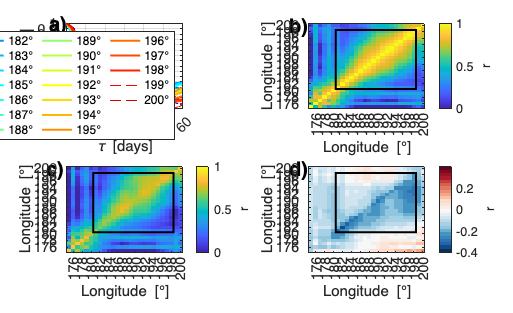


ax1=nexttile;
for k = 1:nDato
    if ismember(stas(k),stas(stind))
        plot(0:nlags,sta_af(k,:),'color',cmapax1(k,:),'linewidth',2); hold on;
    else
        plot(0:nlags,sta_af(k,:),'k--','color',cmapax1(k,:),'linewidth',1); hold on;
    end
end
xlabel('\tau [days]');
ylabel('autocorr [r]');
grid on;
xlim([0 60]); ylim([-0.6 1]);
lats = stas;
set(gca,'ytick',-0.6:0.1:1,'xtick',0:10:100);
set(gca,'fontsize',14);
h1=legend([num2str(transpose(lats)) repmat('\circ',length(lats),1)],'location','northeast'); 
h1.FontSize = 12;
h1.NumColumns = 4;
pa=text(-9,1,'a)'); pa.FontSize=20; pa.FontWeight = 'bold';

ax2=nexttile;
imagesc(stas,stas,Rc); set(gca,'ydir','normal');
xlabel('Longitude [\circ]'); ylabel('Longitude [\circ]'); 
clim([0 1]); h=colorbar; h.Label.String = 'r';
colormap(parula);
rectangle('Position',[stas(stind(1))-0.5 stas(stind(1))-0.5 stas(stind(end))-stas(stind(1))+1 stas(stind(end))-stas(stind(1))+1],'linewidth',2)
set(gca,'fontsize',14);
set(gca,'xtick',174:2:200,'ytick',174:2:200);
colormap(ax2,'parula');
pb=text(170,200,'b)'); pb.FontSize=20; pb.FontWeight = 'bold';

ax3=nexttile;
imagesc(stas,stas,R); set(gca,'ydir','normal');
xlabel('Longitude [\circ]'); ylabel('Longitude [\circ]'); 
clim([0 1]); h=colorbar; h.Label.String = 'r';
colormap(parula);
rectangle('Position',[stas(stind(1))-0.5 stas(stind(1))-0.5 stas(stind(end))-stas(stind(1))+1 stas(stind(end))-stas(stind(1))+1],'linewidth',2)
set(gca,'fontsize',14);
set(gca,'xtick',174:2:200,'ytick',174:2:200);
colormap(ax3,'parula');
pc=text(170,200,'c)'); pc.FontSize=20; pc.FontWeight = 'bold';

ax4=nexttile;
imagesc(stas,stas,R-Rc); set(gca,'ydir','normal');
xlabel('Longitude [\circ]'); ylabel('Longitude [\circ]'); 
clim([-0.4 0.4]); h=colorbar; h.Label.String = 'r';
rectangle('Position',[stas(stind(1))-0.5 stas(stind(1))-0.5 stas(stind(end))-stas(stind(1))+1 stas(stind(end))-stas(stind(1))+1],'linewidth',2)
set(gca,'fontsize',14);
set(gca,'xtick',174:2:200,'ytick',174:2:200);
colormap(ax4,cmapax4);
pd=text(170,200,'d)'); pd.FontSize=20; pd.FontWeight = 'bold';

set(gcf,'PaperPositionMode','manual');
set(gcf,'PaperUnits','centimeters');
set(gcf,'PaperPosition',[0 0 36 28]);
if sav_fig; print('-dpng','-r300',[fig_path,'fig2.png']); end

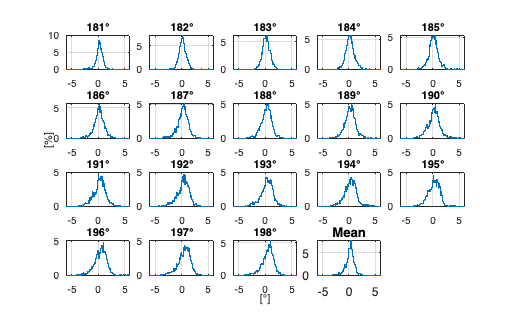



% Make the histogram supplements plot
% % See distributions of each station.
clf;
thevars = NaN(1,nDat);
for k = 1:nDat
    subplot(4,5,k);
    thevars(k) = std(iceedgedt(k,:));
    histN(iceedgedt(k,:),-15:0.1:15,'line','linewidth',1); hold on;
    title(([num2str(stas(stind(k))),'\circ']));
    set(gca,'xtick',-15:5:15); xlim([-6 6]); grid on;
    if k == nDat; xlabel('[\circ]'); end
    if k == 11; ylabel('                                [%]'); end
end
subplot(4,5,nDat+1);
histN(mean(iceedgedt(:,:)),-15:0.1:15,'line','linewidth',1);
set(gca,'xtick',-15:5:15); xlim([-6 6]); grid on; title('Mean');
set(gca,'fontsize',12);
set(gcf,'PaperPositionMode','manual');
set(gcf,'PaperUnits','centimeters');
set(gcf,'PaperPosition',[0 0 32 16]);
if sav_fig; print('-dpng','-r300',[fig_path,'fig_S2_hists.png']); end

### Do LIM

% We will test the first 8 tau0s, each lags out to 20 days.
x = transpose(iceedgedt); % get oriented
disp(['Number of samples = ',num2str(length(find(~isnan(x))))]);

Number of samples = 57547



% fx 
tau0_arr = 1:9                                                          ; % Test these tau0s 
Tau_arr  = 1:60                                                         ; % Create array of Tau's to get error at (out to ~3 weeks)
    
fx_all           = NaN(length(tau0_arr),length(Tau_arr),nDat,length(x)) ; % Fx stored 4d array, [tau0,leadtime,station,time]
epsilon_sta      = NaN(length(tau0_arr),length(Tau_arr),nDat)           ; % Expected error per station
epsilon          = NaN(length(tau0_arr),length(Tau_arr))                ; % Expected error collectively
epsilon_raw      = NaN(length(tau0_arr),length(Tau_arr))                ; % Expected error collectively, not normalized
compL            = zeros(size(tau0_arr))                                ; % Binary, 1 = L was complex, else 0 
nyquists         = zeros(length(tau0_arr),length(Tau_arr))              ; % Binary, 1 = Nyquist frequency found
gamma1max        = zeros(length(tau0_arr),length(Tau_arr))              ; % 
firstnyq         = zeros(size(tau0_arr))                                ; % Smallest tau0 where Nyquist was found

% Run hindcasts for a series of tau0s
for iT0 = 1:length(tau0_arr)
    
    % Do LIM for this tau0
    [L,Q,B,Gtau,C0,Ctau,ualpha,valpha,galpha,tau_decay_alpha,T_mode_oscil] = dolim(x,tau0_arr(iT0));
    if ~isreal(L); compL(iT0) = 1; end
   
    % Loop over lead time array (Tau_arr)
    for iTau = 1:length(Tau_arr) 

        % Check for Nyquists
        nyqtmp = abs(imag(diag(B))*(Tau_arr(iTau)));
        if any((nyqtmp>=3.14) & (nyqtmp<=3.142))
            nyquists(iT0,iTau) = 1;
        end
 
        % Define Green function at this lag 
        G_tau = real(ualpha * diag(galpha).^(Tau_arr(iTau)/tau0_arr(iT0)) * transpose(valpha));
        eps = C0-(G_tau*(C0*transpose(G_tau)));
        for k = 1:nDat
            epsilon_sta(iT0,iTau,k) =  eps(k,k) / nanvar(x(:,k));
        end
        epsilon(iT0,iTau) = trace(eps) / sum(nanvar(x));
        epsilon_raw(iT0,iTau) = trace(eps) / nDat;
        
        % Calculate gamma
        [Psi_tmp,gamma_tmp] = eig(transpose(G_tau)*G_tau);
        gamma1max(iT0,iTau) = max(diag(gamma_tmp));
        
        fx = NaN(nDat,length(x));

        for iT = 1:length(x)-Tau_arr(iTau)    % Loop over timesteps 
        
            tmp = x(iT,:);
            ii = find(isnan(tmp));
            tmp(ii) = 0;
            thisfx = G_tau*transpose(tmp);
            thisfx(ii) = NaN;
            % Fx: compute forecast 
            fx(:,iT+Tau_arr(iTau)) = thisfx;
             
        end    

        fx_all(iT0,iTau,:,:) = fx;

    end

    tmp = find(nyquists(iT0,:) == 1,1,'first'); if isempty(tmp); tmp = 30; end
    firstnyq(iT0) = tmp;
        
end

 
Dimensions look good.
u,v are properly normalized.
All done. Happy Limming :)
 
 
Dimensions look good.
u,v are properly normalized.
All done. Happy Limming :)
 
 
Dimensions look good.
u,v are properly normalized.
All done. Happy Limming :)
 
 
Dimensions look good.
u,v are properly normalized.
All done. Happy Limming :)
 
 
Dimensions look good.
u,v are properly normalized.
All done. Happy Limming :)
 
 
Dimensions look good.
u,v are properly normalized.
All done. Happy Limming :)
 
 
Dimensions look good.
u,v are properly normalized.
All done. Happy Limming :)
 
 
Dimensions look good.
u,v are properly normalized.
All done. Happy Limming :)
 
 
Dimensions look good.
u,v are properly normalized.
All done. Happy Limming :)
 



% Pick your tau_0. We will back off two steps from the earliest Nyquist
tau_0 = find(sum(nyquists) == 1,1,'first')-2;
if isempty(tau_0); tau_0 = 4; end
tau_0 = 4; disp('You selected your own tau.');

You selected your own tau.


disp(['Selected tau0 is ',num2str(tau_0)]);

Selected tau0 is 4



% Pull out the Maximum Amplification Curve (MAC) corresponding to selected
% tau0.
gamma1max = gamma1max(tau_0,:);

% Run the code one more time using tau_0 so we have all the details.
[L,Q,B,Gtau,C0,Ctau,ualpha,valpha,galpha,tau_decay_alpha,T_mode_oscil] = dolim(x,tau_0);

 
Dimensions look good.
u,v are properly normalized.
All done. Happy Limming :)
 


## Analysis of LIM diagnostics

- (1) MAC

- (2) Optimal Structure

- (3) Tau Test

(1) Calculate the Maximum Amplification Curve (MAC)

The MAC is calculated corresponding to each (ranked) eigenvalue (n = nDat). We are looking for peaks some lead time tau > 1 and amplitude > 1. Else, the solution to the linear system does not add information over damped persistence.

tau_m = find(gamma1max == max(gamma1max));
gamma1max2 = [];
for j = 1:max(Tau_arr)
    Gt_taum = real(ualpha * diag(galpha).^(j/tau_0) * transpose(valpha));
    [Psi1,gamma1] = eig(transpose(Gt_taum)*Gt_taum); %[EIGVEC,EIGVAL]
    gamma1 = diag(gamma1);
    [ai ab] = sort(gamma1,'descend');
    gamma1max2 = [gamma1max2  gamma1(ab)];
end

The figure shows the leading eigenvalue corresponds to a significant MAC, peaking at tau = 6. 


tau_peak = [];
peak_amp = [];
legs = [];
clf;
cmap=colormap(jet(nDat));
for k = 1:nDat
    ii = find(gamma1max2(k,:) == max(gamma1max2(k,:)));
    tau_peak = [tau_peak; ii];
    peak_amp = [peak_amp; gamma1max2(k,ii)];
    legs = [legs; {['\gamma',num2str(k)]}];
    plot(gamma1max2(k,:),'color',cmap(k,:),'linewidth',2); hold on;
end

plot(tau_peak,peak_amp,'ko-','linewidth',2,'markersize',8)
for ii = [1 2 3:3:nDat]% 1:length(tau_peak)
    if ii == 1
        text(tau_peak(ii),peak_amp(ii)-0.2,['\gamma',num2str(ii),' at \tau = ',num2str(tau_m)],'Color','k','fontsize',14)
    elseif ii == 2
        text(tau_peak(ii)+0.4,peak_amp(ii)+0.1,['\gamma',num2str(ii)],'Color','k','fontsize',14)
    else
        text(tau_peak(ii)-1.25,peak_amp(ii),['\gamma',num2str(ii)],'Color','k','fontsize',14)
    end
end
xlabel('\tau'); ylabel('amplification'); hline(1);
xlim([-0.5 20]); grid on;
set(gca,'fontsize',14);
set(gcf,'PaperPositionMode','manual');
set(gcf,'PaperUnits','centimeters');
set(gcf,'PaperPosition',[0 0 24 18]);
if sav_fig; print('-dpng','-r300',[fig_path,'fig_4_MAC.png']); end

(2) The leading eigenvalue has a peak > tau = 1 at and amplitude > 1. All other eigenvalues produce MACs that ~ <= 1 peak ampltide and generally fall off sharply after tau =1. Thus, there is only one optimal structure. This should be like saying there is a particular orientation or shape of the ice edge that is associated with high predictability due to stochasitc growth. Initial indications were that this appears when the profile of the ice edge has an anomalously meridional component to it, specifically that the ice is farther north in the west and farther south in the east. Subsequent analysis indicated that the first conclusion, i.e., that only the leading eigenvalue is significant, is robust, but that the second, i.e., a more meridional initial condition produces a more confiedent forecast, was not. Specifically, we determined that the source of the orientation-based skill was due to the 2nd and/or 3rd components of the seasonal cycle, and perhaps most concerning, the treatment of the time series to manage these sources of variability.

Here we plot the loading patterns. We will display values for tau = 3 to 17 to be able to assess the consistency of the structure with tau, but recall that the optimal structure was determined to be at tau = 6 from the previous plot. 

cmap2 = flipud(cbrewer('seq', 'OrRd',17, 'linear'));
cmap = lines;
h = [];
legs = [];
clf;
for k = 3:17
    tau_m_tmp = k;
    Gt_taum_tmp = real(ualpha * diag(galpha).^(tau_m_tmp/tau_0) * transpose(valpha));
    [Psi1,gamma1] = eig(transpose(Gt_taum_tmp)*Gt_taum_tmp); %[EIGVEC,EIGVAL]
    ind = find(diag(gamma1) == max(diag(gamma1)));

    optimStructtmp = real(Psi1(:,ind));
    if sign(optimStructtmp(1)) == -1
        k
        optimStructtmp = optimStructtmp.*-1;
    end

    htmp = plot(optimStructtmp,'-','color',cmap2(k-2,:),'linewidth',0.5,'markersize',10); hold on;
    h = [h; htmp];
    legs = [legs; {['\tau=',num2str(k)]}];

    if k == tau_m
        optimStruct = optimStructtmp;
        Gt_taum = Gt_taum_tmp;
    end
    
end

htmp = plot(optimStruct,'-*','color',cmap2(tau_m,:),'linewidth',2,'markersize',10); hold on; 
h = [h; htmp]; legs = [legs; {['Optimal Structure \tau(\gamma1)=',num2str(tau_m)]}];
htmp = plot(Gt_taum*optimStruct,'-^','linewidth',2,'markersize',10,'color',cmap(1,:));
h = [h; htmp]; legs = [legs; {['Final Structure']}];
xlim([0.5 length(stas(stind))+0.5]); ylim([-0.65 0.65]); grid on;
xl = stas(stind);
ylabel('Loading'); xlabel('station [\circE]'); set(gca,'xtick',1:length(stas(stind)),'xticklabel',xl(1:length(stas(stind))));
h1=legend(h,legs,'location','southeast');
h1.FontSize = 14;
h1.NumColumns = 4;
xlim([0.5 length(stas(stind))+0.5]); ylabel('Maximum Amplitude'); set(gca,'xtick',1:length(stas(stind))); %grid on;
set(gca,'fontsize',14); 
set(gcf,'PaperPositionMode','manual');
set(gcf,'PaperUnits','centimeters');
set(gcf,'PaperPosition',[0 0 24 18]);
if sav_fig; print('-dpng','-r300',[fig_path,'fig3_optiStruct']); end

(3) Conduct the "tau test"

Figure plots the theoretical (expected) error,ε, for a series of tau0 values. We will color code based on whether the tau0 includes Nyquists at tau < tau0 (which invalidates it) in red (if occurs) and we will plot the tau0 used for the model in green. Dashed lines refer to tau0 <= 3. The test is subjective: expected behavior is that ε is insensitive to the choice of tau0, but the tolerance is flexible.

The test shows agreement for tau0 > 3, but we consistently find some deviation for tau0 <= 3. I speculate that the lower errors for tau0 <= 3 days is associated with artificial smoothing of short-term variability by a combination of the coarseness of the gridded product, which is axacerbated by the regriddiing procedure, as well as the nature of the underlying data, which are temporal aggregates of a limted number of overpasses. It is probably best to avoid small tau0, though the errors incurred is not expected to be large.

clf;
plot([0 Tau_arr],[transpose(zeros(size(epsilon(compL==0 & find(compL==0) <= 3,1))));transpose(epsilon(compL==0 & find(compL==0) <= 3,:))],'b--','linewidth',1); hold on;
h1=plot([0 Tau_arr],[transpose(zeros(size(epsilon(compL==0 & find(compL==0) > 3,1))));transpose(epsilon(compL==0 & find(compL==0) > 3,:))],'b','linewidth',1);
try
    plot([0 Tau_arr],[transpose(zeros(size(epsilon(compL==1 & find(compL==1) <= 3,1))));transpose(epsilon(compL==1 & find(compL==1) <= 3,:))],'r--','linewidth',1); 
end
try
    h2=plot([0 Tau_arr],[transpose(zeros(size(epsilon(compL==1 & find(compL==1) > 3,1))));transpose(epsilon(compL==1 & find(compL==1) > 3,:))],'r','linewidth',1);
end
h3=plot([0 Tau_arr],[transpose(zeros(size(epsilon(tau_0,1))));transpose(epsilon(tau_0,:))],'g','linewidth',3);
ylim([0 1]);
xlabel('\tau'); ylabel('\epsilon^2 (\tau,\tau_0)'); title(['Tau test for \tau ',num2str(min(tau0_arr)),'-',num2str(max(tau0_arr))]); grid on;
try
h=legend([h1(1) h2(1) h3],'\tau_0 (L is real; no Nyquists)','\tau_0 (L is complex; has Nyquists)',['Chosen \tau_0 = ',num2str(tau_0)],'location','southeast');
catch
h=legend([h1(1) h3],'\tau_0 (L εs real; no Nyquists)',['Chosen \tau_0 = ',num2str(tau_0)],'location','southeast');
end
set(gca,'fontsize',16); grid on;
set(gcf,'PaperPositionMode','manual');
set(gcf,'PaperUnits','centimeters');
set(gcf,'PaperPosition',[0 0 24 18]);
if sav_fig; print('-dpng','-r300',[fig_path,'fig_S1_tauTest']); end

## Forecasts of opportunity

Forecasts of opportunity comprise initial conditions (IC) that are associated with particularly skillful forecasts. Skill is a distribution so a threshold is needed to classify skillful ICs. Penland et al. (2021) recommends the top tercile. Threre are two ways to idenfity the values using the LIM data:

(1) Optimal Projection: Recall that the optimal structure is the loading pattern representing the optimal IC profile for the iceedge w.r.t. predictablity. While we found that the most salient features were linked to the seasonal cycle, the optimal loading pattern can still be projected onto the ICs to isolate optimal times.

(2) Signal-to-Noise: A value, rho_infinite may be calculated from the signal-to-noise ratio, S, following Albers and Newman (2021), as


$$\rho_{\infty } \left(t,\tau \right)=\frac{S^2 \left(t,\tau \right)}{{\left.{\left(S\right.}^2 \left(t,\tau \right)+1\right)S^2 \left(t,\tau \right)}^{0\ldotp 5} }$$


Albers, J. and M. Newman (2021) Subseasonal predictability of the North Atlantic Oscillation. Environmental Research Letters, 16, 044024. [https://doi.org/10.1088/1748-9326/abe781](https://doi.org/10.1088/1748-9326/abe781) 

Penland, C., M.D. Fowler, D.L. Jackson, and R. Cifeli (2021) Forecasts of opportunity for northern California soil moisture. Land, 10, 713. [https://doi.org/10.3390/land10070713](https://doi.org/10.3390/land10070713) 

(1) Optimal Projection

- Use upper tercile for defining.

optProj = NaN(length(x),1);
optProjF = NaN(length(x),1); 
for k = 1:length(x)-tau_m
    optProj(k) = nansum(optimStruct'.*x(k,:)); 
    optProjF(k) = nansum((Gt_taum*optimStruct)'.*x(k+tau_m,:)); 
end
optProj(mm>3) = NaN;
optProjF(mm>3) = NaN;
% top tercile 
% i find that the ddsitrubtion of optProj includes both positive and
% negative values and that the more positive, the better the fx
indgoodfx = find(abs(optProj) > prctile(abs(optProj),66.66));

histogram(abs(optProj),-10:0.1:10,'normalization','probability');
xlim([0 8])



(2) Signal-to-Noise

## Error Assessment

% Calculate errors
indalbsap = find(albsalim>(nanmean(albsalim)+1*nanstd(albsalim)));
indalbsan = find(albsalim<(nanmean(albsalim)-1*nanstd(albsalim)));
indalbsam = find(albsalim>(nanmean(albsalim)-1*nanstd(albsalim))&albsalim<(nanmean(albsalim)+1*nanstd(albsalim)));

fx_tmp = squeeze(fx_all(tau_0,:,:,:));
normErrLIM = NaN(nDat,length(Tau_arr));
normErrPers = NaN(nDat,length(Tau_arr));
ar1 = NaN(nDat,length(Tau_arr));
normErrLIMgoodfx = NaN(nDat,length(Tau_arr));
normErrLIMalbsapfx = NaN(nDat,length(Tau_arr));
normErrLIMalbsanfx = NaN(nDat,length(Tau_arr));
normErrLIMalbsamfx = NaN(nDat,length(Tau_arr));
LIMerrraw = NaN(length(x),nDat,length(Tau_arr));
normErrLIMr = NaN(nDat,length(Tau_arr));
normErrPersr = NaN(nDat,length(Tau_arr));
ar1r = NaN(nDat,length(Tau_arr));
normErrLIMgoodfxr = NaN(nDat,length(Tau_arr));
normErrLIMalbsapfxr = NaN(nDat,length(Tau_arr));
normErrLIMalbsanfxr = NaN(nDat,length(Tau_arr));
normErrLIMalbsamfxr = NaN(nDat,length(Tau_arr));
for k = 1:nDat
    for h = 1:length(Tau_arr)
        normErrLIM(k,h) = nanvar(squeeze(fx_tmp(h,k,:))-x(:,k)) / nanvar(x(:,k)); 
        normErrPers(k,h) = nanvar(x(Tau_arr(h)+1:end,k)-x(1:end-Tau_arr(h),k)) / nanvar(x(:,k)); 
        aproc = exp((-1/sta_eF(k))*Tau_arr(h)) * x(:,k);
        ar1(k,h) = nanvar(x(Tau_arr(h)+1:end,k) - aproc(1:end-Tau_arr(h))) / nanvar(x(:,k)); 
        normErrLIMgoodfx(k,h) = nanvar(squeeze(fx_tmp(h,k,indgoodfx))-x(indgoodfx,k)) / nanvar(x(indgoodfx,k)); 

        normErrLIMalbsapfx(k,h) = nanvar(squeeze(fx_tmp(h,k,indalbsap))-x(indalbsap,k)) / nanvar(x(indalbsap,k)); 
        normErrLIMalbsanfx(k,h) = nanvar(squeeze(fx_tmp(h,k,indalbsan))-x(indalbsan,k)) / nanvar(x(indalbsan,k)); 
        normErrLIMalbsamfx(k,h) = nanvar(squeeze(fx_tmp(h,k,indalbsam))-x(indalbsam,k)) / nanvar(x(indalbsam,k)); 
        LIMerrraw(:,k,h) = (squeeze(fx_tmp(h,k,:))-x(:,k)) / nanvar(x(:,k));

        normErrLIMr(k,h) = nanvar(squeeze(fx_tmp(h,k,:))-x(:,k)); 
        normErrPersr(k,h) = nanvar(x(Tau_arr(h)+1:end,k)-x(1:end-Tau_arr(h),k)); 
        aprocr = exp((-1/sta_eF(k))*Tau_arr(h)) * x(:,k);
        ar1r(k,h) = nanvar(x(Tau_arr(h)+1:end,k) - aproc(1:end-Tau_arr(h))); 
        normErrLIMgoodfxr(k,h) = nanvar(squeeze(fx_tmp(h,k,indgoodfx))-x(indgoodfx,k)); 

        normErrLIMalbsapfxr(k,h) = nanvar(squeeze(fx_tmp(h,k,indalbsap))-x(indalbsap,k)); 
        normErrLIMalbsanfxr(k,h) = nanvar(squeeze(fx_tmp(h,k,indalbsan))-x(indalbsan,k)); 
        normErrLIMalbsamfxr(k,h) = nanvar(squeeze(fx_tmp(h,k,indalbsam))-x(indalbsam,k)); 
    end
end

errsattau = nanmean(squeeze(LIMerrraw(:,:,7)),2);


cmap = lines;
clf;
plot([0 Tau_arr],[0 mean(normErrLIM)],'ko-','color',cmap(1,:),'linewidth',2); hold on;
plot([0 Tau_arr],[0 epsilon(tau_0,:)],'ko-','color',cmap(2,:),'linewidth',1);
plot([0 Tau_arr],[0 mean(ar1)],'ko-','color',cmap(3,:),'linewidth',2);
plot([0 Tau_arr],[0 mean(normErrPers)],'ko-','color',cmap(4,:),'linewidth',2);
plot([0 Tau_arr],[0 mean(normErrLIMgoodfx)],'ko-','color',cmap(5,:),'linewidth',2);

plot([0 Tau_arr],[0 mean(normErrLIMalbsapfx)],'ko-','color',cmap(6,:),'linewidth',2);
plot([0 Tau_arr],[0 mean(normErrLIMalbsanfx)],'ko-','color',cmap(7,:),'linewidth',2);

grid on; hline(0.4); ylim([0 1.1]); xlim([0 20]);
set(gca,'ytick',0:0.1:1.1,'xtick',0:21);
xlabel('\tau [days]'); ylabel('Error variance'); 
%title('Fx Errors'); 
grid on;
legend('LIM','Expected Error','AR1','Persistence','Optimal Fx','+ALBSA','-ALBSA','location','northwest');
set(gca,'fontsize',14);
set(gcf,'PaperPositionMode','manual');
set(gcf,'PaperUnits','centimeters');
set(gcf,'PaperPosition',[0 0 30 18]);
%print -dpng -r300 fig6_meanerror1.png

cmap = lines;
clf;
plot([0 Tau_arr],[0 mean(normErrLIMr)],'ko-','color',cmap(1,:),'linewidth',2); hold on;
plot([0 Tau_arr],[0 epsilon_raw(tau_0,:)],'ko-','color',cmap(2,:),'linewidth',1);
plot([0 Tau_arr],[0 mean(ar1r)],'ko-','color',cmap(3,:),'linewidth',2);
plot([0 Tau_arr],[0 mean(normErrPersr)],'ko-','color',cmap(4,:),'linewidth',2);
plot([0 Tau_arr],[0 mean(normErrLIMgoodfxr)],'ko-','color',cmap(5,:),'linewidth',2);

plot([0 Tau_arr],[0 mean(normErrLIMalbsapfxr)],'ko-','color',cmap(6,:),'linewidth',2);
plot([0 Tau_arr],[0 mean(normErrLIMalbsanfxr)],'ko-','color',cmap(7,:),'linewidth',2);

tmp = 0:0.1:1.1;
ylabs = [];
for k = 1:length(tmp)
    ylabs = [ylabs; {[num2str(tmp(k)),' (',num2str(tmp(k)*111),')']}];
end

grid on; hline(0.4); ylim([0 1.1]); xlim([0 20]); 
set(gca,'ytick',0:0.1:1.1,'xtick',0:21,'yticklabel',ylabs);
xlabel('\tau [days]'); ylabel('Mean Error [\circ, km]'); 
%title('Fx Errors'); 
grid on;
legend('LIM','Expected Error','AR1','Persistence','Optimal Fx','+ALBSA','-ALBSA','location','northwest');
set(gca,'fontsize',14);
set(gcf,'PaperPositionMode','manual');
set(gcf,'PaperUnits','centimeters');
set(gcf,'PaperPosition',[0 0 30 18]);
%print -dpng -r300 fig6_meanerrorraw1.png


xx = 0:1/24:60;
YY = NaN(nDat,4);
for k = 1:nDat
    yy = interp1([0 Tau_arr],[0 normErrPers(k,:)],xx);
    tmp = xx(find(yy > 0.4,1,'first')); if isempty(tmp); tmp = 60; end
    YY(k,1) = tmp;
    yy = interp1([0 Tau_arr],[0 ar1(k,:)],xx);
    tmp = xx(find(yy > 0.4,1,'first')); if isempty(tmp); tmp = 60; end
    YY(k,2) = tmp;
    yy = interp1([0 Tau_arr],[0 normErrLIM(k,:)],xx);
    tmp = xx(find(yy > 0.4,1,'first')); if isempty(tmp); tmp = 60; end
    YY(k,3) = tmp;  
    yy = interp1([0 Tau_arr],[0 normErrLIMgoodfx(k,:)],xx);
    tmp = xx(find(yy > 0.4,1,'first')); if isempty(tmp); tmp = 60; end
    YY(k,4) = tmp;  
end
YYrem1 = YY;
save /Users/ccox/Documents/Projects/2024/bering_ice/data/rem1.mat YYrem1;


yy = interp1([0 Tau_arr],[0 mean(normErrPers)],xx);
disp(['Persistence skill at 0.4 ev = ',num2str(xx(find(yy > 0.4,1,'first'))),' days']); 
yy = interp1([0 Tau_arr],[0 mean(ar1)],xx);
disp(['AR1 skill at 0.4 ev = ',num2str(xx(find(yy > 0.4,1,'first'))),' days']); 
yy = interp1([0 Tau_arr],[0 mean(normErrLIM)],xx);
disp(['LIM skill at 0.4 ev = ',num2str(xx(find(yy > 0.4,1,'first'))),' days']); 
yy = interp1([0 Tau_arr],[0 mean(normErrLIMgoodfx)],xx);
disp(['LIM optimal skill at 0.4 ev = ',num2str(xx(find(yy > 0.4,1,'first'))),' days']); 






plot(albsalim,errsattau,'.');

indgoodfx = find(abs(optProj) > prctile(abs(optProj),50));
indbadfx = find(abs(optProj) < prctile(abs(optProj),50));

al = albsalim - nanmean(albsalim);
bar([nanmean(al(indgoodfx)) nanmean(al(indbadfx))]);

% Case Study

clf;
cmap = lines;
ind = find(yyyy == 2023);

yyaxis left 

theind = 1:9;
thedata = nanmean(x(ind,theind),2);
ys = unique(yyyy);
thedataclim = NaN(length(ys),365,nDat);
for h = 1:nDat
    for k = 1:length(ys)
        ii = find(yyyy == ys(k));
        doys = iceedge_dn(ii) - datenum([ys(k) 1 0 0 0 0]);
        tmp = x(ii,h); %nanmean(x(ii,:),2);
        if doys(end) == 366
            doys(end) = [];
            tmp(end) = [];
        end
        thedataclim(k,doys,h) = tmp;
    end
end
clf;
plot(squeeze(nanmean(thedataclim,1)),'k')
hold on
plot(squeeze(nanmean(nanmean(thedataclim,1),3)),'r','linewidth',2)




delta = nanmean(thedata); %nanmean(thedata) - nanmean(nanmean(iceedge(:,ind)));
h1=plot(iceedge_dn(ind),thedata,'linewidth',2,'color',cmap(2,:)); hold on;
%h1a=plot(iceedge_dn(ind),nanmean(thedataclim),'linewidth',2,'color',cmap(1,:));
%plot(iceedge_dn(ind),nanmean(iceedge(:,ind)),'linewidth',2);
% fx_all: [tau0 lead station time]

fx_all_case = squeeze(fx_all(tau_0,:,theind,ind));

for initday = 1:3:length(ind)
    ds = [];
    val = [];
    for fxlead = 0:7      
        if fxlead == 0
            subi = ind(initday);
            ds = [ds; iceedge_dn(subi)];
            val = [val; thedata(initday)];
            if ismember(ind(initday),indgoodfx)
                %h2b=plot(ds,val-delta,'k.','markersize',12);
                %h2a=plot(ds,val-delta,'ko','markersize',12);
                h2b=plot(ds,val,'k.','markersize',12);
                h2a=plot(ds,val,'ko','markersize',12);
            else
                %h2b=plot(ds,val-delta,'k.','markersize',12);
                h2b=plot(ds,val,'k.','markersize',12);
            end
        else
            subi = ind(initday)+fxlead-1;
            if subi > length(iceedge_dn); continue; end
            ds = [ds; iceedge_dn(subi)];
            val = [val; nanmean(fx_all_case(fxlead,:,initday))];
        end
    end
    %h3=plot(ds,val-delta,'k-');
    h3=plot(ds,val,'k-');
end
set(gca,'xtick',iceedge_dn(ind(1)-1):7:iceedge_dn(ind(1)+92));
xlim([iceedge_dn(ind(1)-1) iceedge_dn(ind(1)+92)]);
datetick('x','mmmdd','keepticks','keeplimits')
grid on;
ylabel('Rel. Latitude [\circ]');
ylim([-3.1 3.1]);
set(gca,'fontsize',20);

yyaxis right

h4=plot(iceedge_dn(ind),albsalim(ind),'linewidth',1,'color',cmap(1,:)); 
ylim([-800 800]);
ylabel('ALBSA [m]');

ax = gca;
ax.YAxis(1).Color = cmap(2,:);
ax.YAxis(2).Color = cmap(1,:);

legend([h1 h2b h2a h3 h4],'Observation','Initialization','Initialization Optimal', ...
    'Forecast','ALBSA','location','northwest');

set(gca,'fontsize',20);
set(gcf,'PaperPositionMode','manual');
set(gcf,'PaperUnits','centimeters');
set(gcf,'PaperPosition',[0 0 40 18]);
print -dpng -r300 fig7_casestudy_west.png